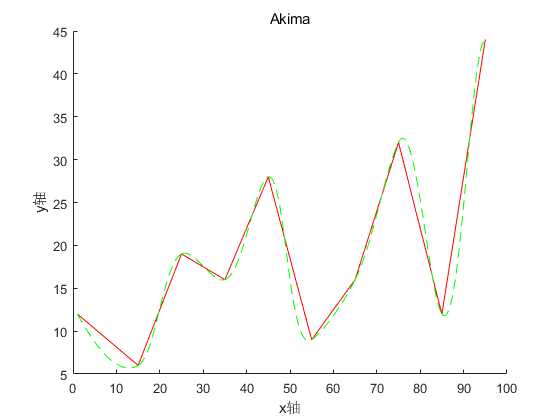

%离散点进行Akima拟合的主程序

clear;  %每次开始就要清除缓存

%最大轮廓误差
MaxSmoothError = 1000; 

line = struct(...
        "start",{},...            %起始点
        "end",{},...              %终止点
        "Ustart",{},...           %参数化后的起始点
        "Uend",{},...             %参数化后的终止点
        "length",{},...           %长度
        "right",{},...            %双弦高误差测试
        "flag",{},...             %切线误差测试
        "lineslpoe",{},...        %线段斜率
        "lineslopeVector",{},...  %线段斜率向量
        "startslopeVector",{},... %经五点算法得到的每个线段起始点斜率向量  
        "endslopeVector",{}, ...  %经五点算法得到的每个线段终止点斜率向量
        "startslope",{}, ...      %经五点算法得到的每个线段起始点斜率
        "endslope",{});           %经五点算法得到的每个线段终止点斜率
 %{ 
P0 = [0,0.01];
P1 = [0.013,0.041];
P2 = [0.024,0.021];
P3 = [0.035,0.062];
P4 = [0.047,0.028];
P5 = [0.058,0.09];
P6 = [0.062,0.013];
P7 = [0.088,0.042];
P8 = [0.1,0.012];
P9 = [0.16,0.084];
%}
  
% 定义控制点
P0 = [1,12];
P1 = [15,6];
P2 = [25,19];
P3 = [35,16];
P4 = [45,28];
P5 = [55,9];
P6 = [65,16];
P7 = [75,32];
P8 = [85,12];
P9 = [95,44];

%原始坐标点数组
Parray = [P0;P1;P2;P3;P4;P5;P6;P7;P8;P9];

%求原始坐标点间的距离，保存在数组lineLengths中
lineLengths = Dot2dotDistance(Parray);

%参数化后的数组
Uarray = Parameterization(Parray,lineLengths);

%经五点算法得到的每个点斜率
[slope,slopeVector] = FiveAkima(Parray,Uarray);

%线段的起始点
start = Parray(1:end-1,:);
%线段的结束点
End   = Parray(2:end,:);
   
for i = 1:length(Parray)-1
    line(i).start            = start(i,:);
    line(i).end              = End(i,:);
    line(i).Ustart           = Uarray(i);
    line(i).Uend             = Uarray(i+1);
    line(i).length           = lineLengths(i);
    line(i).right            = 0;
    line(i).flag             = 0;
    line(i).lineslope        = (line(i).start(2)-line(i).end(2)) / (line(i).start(1)-line(i).end(1));
    line(i).lineslopeVector  = slopeVector(i+2,:);
    line(i).startslopeVector = slope(i,:);
    line(i).endslopeVector   = slope(i+1,:);
    line(i).startslope       = line(i).startslopeVector(2)/line(i).startslopeVector(1);
    line(i).endslope         = line(i).endslopeVector(2)/line(i).endslopeVector(1);
end


%计算线段间的夹角
angleArr = LineAngle(Parray,lineLengths);

%进行双弦高误差准则判断
line = ChordHeightError(angleArr,lineLengths,line,MaxSmoothError);

%进行切线误差测试
line = TangentError(line,MaxSmoothError);

%求Akima表达式中的系数A,B,C,D,并进行拟合
AkimaInterp(line);